% Given parameters
alpha = 1+mod(109,3);           % Maximum passband ripple in dB
stopband_attenuation = 40; % Minimum stopband attenuation in dB
Fs = 720;            % Sampling frequency in samples/sec
Fp = 10;             % Passband edge frequency in Hz
Fstop = 20;          % Stopband edge frequency in Hz

% Calculate normalized cutoff frequency (Wc)
Wc = 2 * Fp / Fs;
Ws= 2*Fstop/Fs;
% Determine filter order (N) using the formula for Butterworth filter
[n,Wn] = buttord(Wc,Ws,alpha,40) 

n = 8

Wn = 0.0313

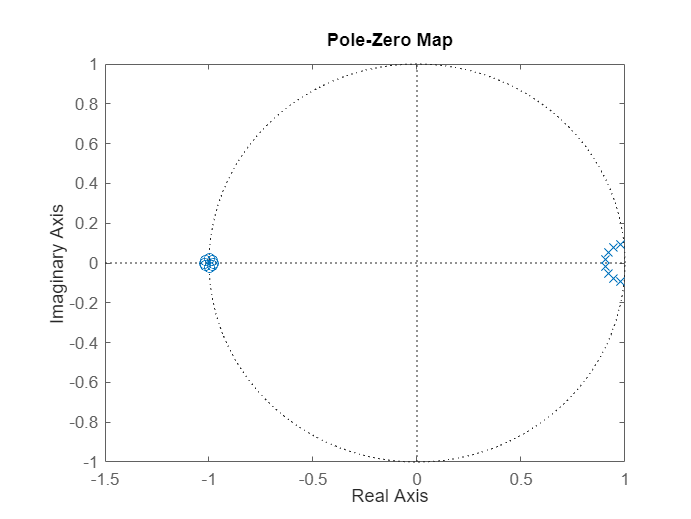

% Design the Butterworth filter
[z,p] = butter(n,Wn);
sos = tf(z,p,1/Fs);
pzmap(sos)

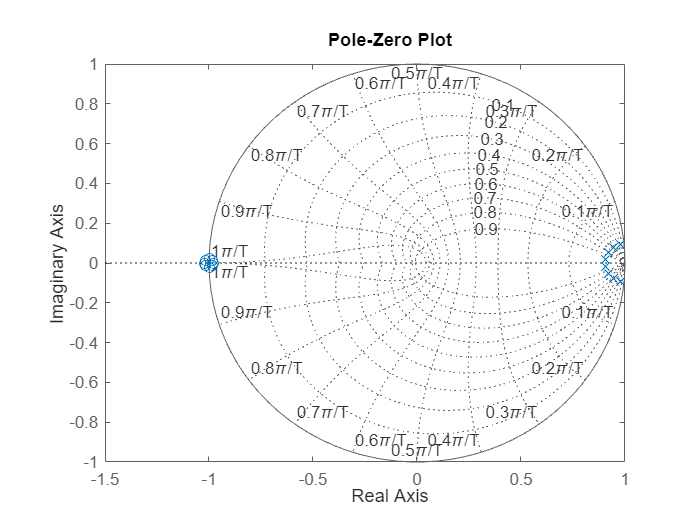

% Plot the pole-zero plot
figure;
pzmap(sos);
title('Pole-Zero Plot');
grid on;

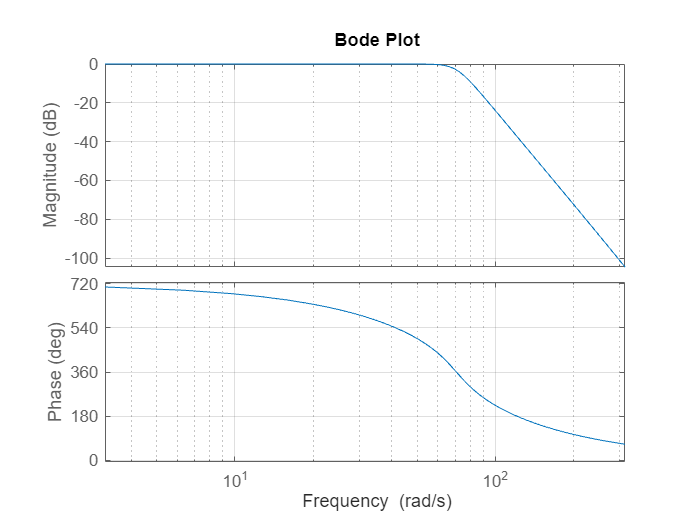

% Plot the Bode plot
figure;
%f=0:0.5:50;
f=linspace(0,50,100);
bode(sos,2*pi*f);
title('Bode Plot');
grid on;

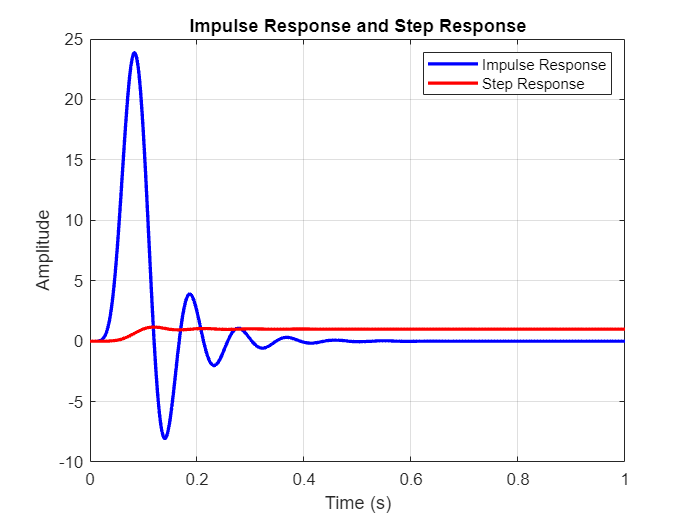

% Define the time vector for 1 second
t = 0:1/Fs:1;

% Compute the impulse response of the filter
impulse_response = impulse(sos, t);

% Compute the step response of the filter
step_response = step(sos, t);

% Plot the impulse response and step response on the same graph
figure;
plot(t, impulse_response, 'b', 'LineWidth', 2, 'DisplayName', 'Impulse Response');
hold on;
plot(t, step_response, 'r', 'LineWidth', 2, 'DisplayName', 'Step Response');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response and Step Response');
legend('show');
grid on;

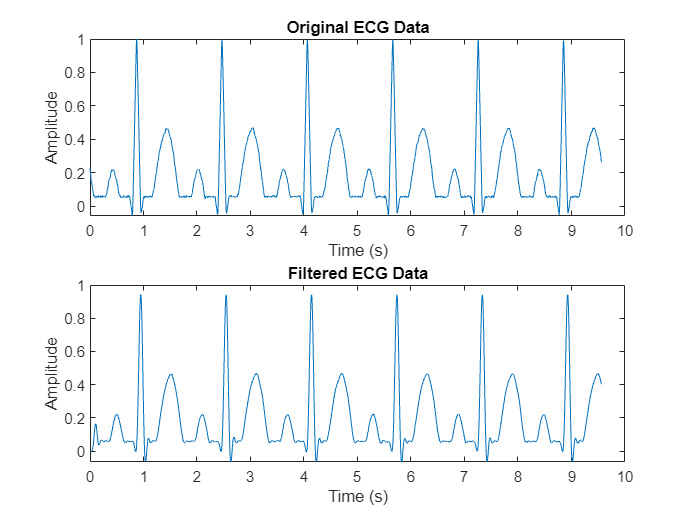

ecg_signal = load('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-6\ECG_Data.txt');
filtered_signal = filter(z,p,ecg_signal);

t = (0:length(ecg_signal)-1) / Fs;

subplot(2,1,1);
plot(t, ecg_signal);
title('Original ECG Data');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered ECG Data');
xlabel('Time (s)');
ylabel('Amplitude');